# FIR Filter Transient

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a watermarked signal. For more information, see the *Generating Signals and Common Signal Operations* module.

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:3*fs);
t = ((0:numel(flute)-1)/fs)';
yin = chirp(t,2200,t(end),2500);
marked = flute + yin*0.0005;

This code creates the FIR filter from ealier in this module.

designedFIR = designfilt("bandpassfir", ...
    "StopbandFrequency1",2100,"PassbandFrequency1",2200, ...
    "PassbandFrequency2",2500,"StopbandFrequency2",2600, ...
    "StopbandAttenuation1",60,"PassbandRipple",1, ...
    "StopbandAttenuation2",60,"SampleRate",fs)

designedFIR =  digitalFilter with properties:

            Coefficients: [1.6040e-04 -6.9352e-04 -1.4020e-04 -3.1624e-05 -3.5427e-05 -5.6165e-05 -3.5046e-05 4.8691e-05 1.4048e-04 1.3552e-04 -2.0800e-05 -2.3948e-04 -3.1884e-04 -1.1455e-04 2.8287e-04 5.5342e-04 3.9111e-04 -1.8701e-04 … ] (1×317 double)

   Specifications:
       FrequencyResponse: 'bandpass'
         ImpulseResponse: 'fir'
              SampleRate: 16000
          PassbandRipple: 1
      StopbandFrequency1: 2100
      PassbandFrequency1: 2200
      PassbandFrequency2: 2500
      StopbandFrequency2: 2600
    StopbandAttenuation1: 60
    StopbandAttenuation2: 60
            DesignMethod: 'equiripple'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


yfir = filter(designedFIR,marked);

## Task 1

Look at the code at the top of the script. A bandpass FIR filter has been created using the generated code from the **Design Filters** task.

Depending on your application, different filter specifications may be important to you. Filter order is a common concern because it affects computation time.

To see the filter order for the provided filter, you can use the `filtord` function:

`o` `=` `filtord``(``df``)`

o = filtord(designedFIR)

o = 316

## Task 2

For FIR filters, the order also determines the size of the filter transient.

You can confirm this by looking at the impulse response of the filter:

`[``h``,``t``]` `=` `impz``(``df``,``n``,``fs``)`

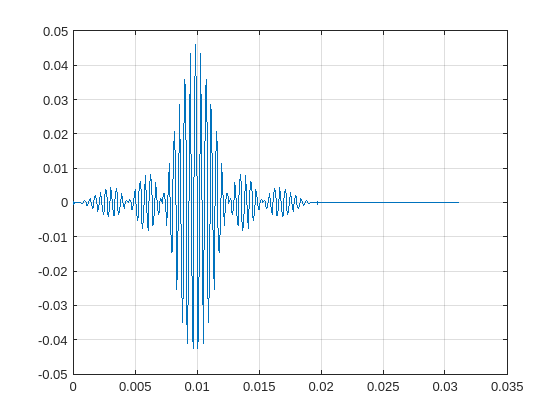

[hi,ti] = impz(designedFIR,500,fs);
plot(ti,hi)
grid on

## Task 3

Based on the impulse response plot, about the first 0.02 seconds of the filtered signal will not be accurate. To find the precise value, use the filter order as an index to the time vector:

`t``(``filterorder``)`

tc = t(o)

tc = 0.0197

## Task 4

Will you be able to see the filter transient in the time-domain plot? You can try adding a vertical line to the time-domain plot where the filter transient ends.

`xline``(``time``)`

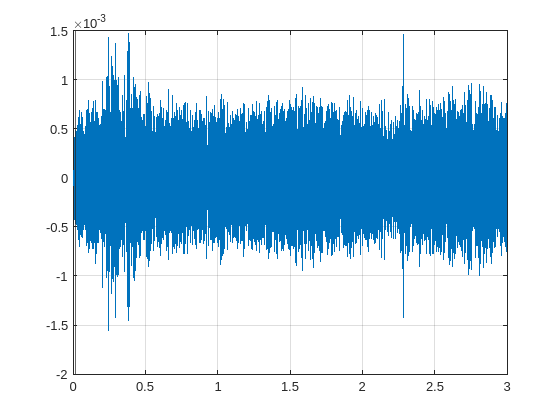

plot(t,yfir)
grid on
xline(tc)